% Greeks Version!!!
clc; clear;

XTrain = {};
YTrain = {};
XTest = {};
YTest = {};

% Prompt the user for the data directory
fprintf('Please pick the data directory');

Please pick the data directory

dataFolder = uigetdir();
filePattern = fullfile(dataFolder, '*.txt');
theFiles = dir(filePattern);

% DataTable Options
varNames = {'Time','Type','Constant','AF7','AF8','TP10','TP9'} ;
varTypes = {'char','char','double','double','double','double','double'} ;
delimiter = ',';
dataStartLine = 3;
extraColRule = 'ignore';
opts = delimitedTextImportOptions('VariableNames',varNames,...
                                'VariableTypes',varTypes,...
                                'Delimiter',delimiter,...
                                'DataLines', dataStartLine,...
                                'ExtraColumnsRule',extraColRule);

% Extract the data from the raw files
fprintf('Processing the Data!');

Processing the Data!

for f = 1 : length(theFiles)
    % File Information
    baseFileName = theFiles(f).name;
    fullFileName = fullfile(theFiles(f).folder, baseFileName);
    fileNameCodes = strsplit(baseFileName(1:end-4), '_');
    dataType = fileNameCodes{3};

    display(baseFileName);

    % Import csv's into datatable
    datatable=readtable(fullFileName,opts);

    % Only keep the pertinent data
    datatable = datatable(string(datatable.Type) == '/muse/elements/alpha_absolute' ...
                        | string(datatable.Type) == '/muse/elements/beta_absolute' ...
                        | string(datatable.Type) == '/muse/elements/delta_absolute' ...
                        | string(datatable.Type) == '/muse/elements/theta_absolute' ...
                        | string(datatable.Type) == '/muse/elements/gamma_absolute', :);

    % Fix Timestamp (drop the ".00" and convert to double)
    for i = 1:height(datatable)
        time = char(datatable.Time(i));
        if (time(end-2:end) == ".00")
            time = time(1:end-3);
        end
        datatable.Time(i) = {time};
    end
    datatable.Time = str2double(datatable.Time);
    
    % Load Data into a Cell Array of BrainData class
    L = datatable.Time(end) - datatable.Time(1);    % Signal Length
    d = 5;                                          % Number of points per set
    n = ceil(height(datatable) / d);                % Number of sets
    P = L / n;                                      % Period
    Fs = 1 / P;                                     % Frequency

    data = cell(n,1);
    dataIndex = 1;
    threshold = 3;
    thresholdCorrection = 3;
    defaultValue = 0;
    
    currentTime = datatable.Time(1);
    previousTime = currentTime;

    currentData = {};
    currentData.Time = currentTime;
    currentData.Alpha = double(0.0);
    currentData.Beta = double(0.0);
    currentData.Delta = double(0.0);
    currentData.Theta = double(0.0);
    currentData.Gamma = double(0.0);
    
    currentCount = 0;
    for i = 1:height(datatable)
        currentCount = currentCount + 1;

        currentTime = datatable.Time(i);
        currentType = datatable.Type(i);
%         currentVal = (10.^datatable.AF7(i) + 10.^datatable.AF8(i) + 10.^datatable.TP9(i) + 10.^datatable.TP10(i)) / 4;
        currentVal = datatable.Constant(i);

        if abs(currentVal) > threshold
            currentVal = sign(currentVal) * thresholdCorrection;
        end

        if currentTime ~= previousTime || currentCount > 5
            if currentCount > 5 && currentTime == previousTime
%                 fprintf("MORE: %d %.6f\n", dataIndex, currentTime);
            end
            currentCount = 1;
            data(dataIndex) = {currentData};
            dataIndex = dataIndex + 1;
            currentData = {};
            currentData.Time = currentTime;
            currentData.Alpha = double(defaultValue);
            currentData.Beta  = double(defaultValue);
            currentData.Delta = double(defaultValue);
            currentData.Theta = double(defaultValue);
            currentData.Gamma = double(defaultValue);
            previousTime = currentTime;
        end

        if contains(currentType, "alpha")
            currentData.Alpha = currentVal;
        elseif contains(currentType, "beta")
            currentData.Beta = currentVal;
        elseif contains(currentType, "delta")
            currentData.Delta = currentVal;
        elseif contains(currentType, "theta")
            currentData.Theta = currentVal;
        elseif contains(currentType, "gamma")
            currentData.Gamma = currentVal;
        end
    end
    
    data = struct2table(cell2mat(data));
    
    % Collect Training Samples
    initial_offset = 30;
    num_samples = 2;
    sample_duration = 20;
    sample_spacing = 10;

    for i = 1:num_samples
        offset = initial_offset + (sample_duration + sample_spacing) * (i - 1);
        [startIndex, endIndex] = startEndIdx(data, offset, sample_duration);
        
        Features = data{startIndex:endIndex, 2:end}';
%         Features = [data.Alpha(start_index:end_index)...
%                     data.Beta(start_index:end_index)...
%                     data.Delta(start_index:end_index)...
%                     data.Theta(start_index:end_index)...
%                     data.Gamma(start_index:end_index)]';
%         if mod(size(Features,2),2) ~= 0
%             Features = Features(:,1:end-1);
%         end
%         Features = (Features(:,1:2:end) + Features(:,2:2:end)) / 2;
%         Features = normalize(Features);
        XTrain = [XTrain; Features];
        YTrain = [YTrain; dataType];
    end

    % Collect Test Samples
    initial_offset = 50;
    num_samples = 3;
    sample_duration = 3;
    sample_spacing = 47;

    for i = 1:num_samples
        offset = initial_offset + (sample_duration + sample_spacing) * (i - 1);
        [startIndex, endIndex] = startEndIdx(data, offset, sample_duration);
        
        if startIndex == 0
            continue
        end

        Features = data{startIndex:endIndex, 2:end}';
%         Features = [data.Alpha(start_index:end_index)...
%                     data.Beta(start_index:end_index)...
%                     data.Delta(start_index:end_index)...
%                     data.Theta(start_index:end_index)...
%                     data.Gamma(start_index:end_index)]';
%         if mod(size(Features,2),2) ~= 0
%             Features = Features(:,1:end-1);
%         end
%         Features = (Features(:,1:2:end) + Features(:,2:2:end)) / 2;
%         Features = normalize(Features);
        XTest = [XTest; Features];
        YTest = [YTest; dataType];
    end

end

baseFileName = '2_1_1_0_0.txt'

baseFileName = '2_1_2_0_0.txt'

baseFileName = '2_1_3_0_0.txt'

baseFileName = '2_1_5_0_0.txt'

baseFileName = '2_1_7_0_0.txt'

baseFileName = '3_1_1_0_0.txt'

baseFileName = '3_1_2_0_0.txt'

baseFileName = '3_1_3_0_0.txt'

baseFileName = '3_1_5_0_0.txt'

baseFileName = '3_1_7_0_0.txt'

baseFileName = '4_1_1_0_0.txt'

baseFileName = '4_1_2_0_0.txt'

baseFileName = '4_1_3_0_0.txt'

baseFileName = '4_1_5_0_0.txt'

baseFileName = '4_1_7_0_0.txt'

baseFileName = '5_1_1_0_0.txt'

baseFileName = '5_1_2_0_0.txt'

baseFileName = '5_1_3_0_0.txt'

baseFileName = '5_1_5_0_0.txt'

baseFileName = '5_1_7_0_0.txt'

baseFileName = '6_1_1_0_0.txt'

baseFileName = '6_1_2_0_0.txt'

baseFileName = '6_1_3_0_0.txt'

baseFileName = '6_1_5_0_0.txt'

baseFileName = '6_1_7_0_0.txt'

baseFileName = '7_1_1_0_0.txt'

baseFileName = '7_1_2_0_0.txt'

baseFileName = '7_1_3_0_0.txt'

baseFileName = '7_1_5_0_0.txt'

baseFileName = '7_1_7_0_0.txt'

% Quick Plot of Training Data
figure
plot(XTrain{1}')
xlabel("Time Step")
title("Training Observation 1")
numFeatures = size(XTrain{1},1)

numFeatures = 5

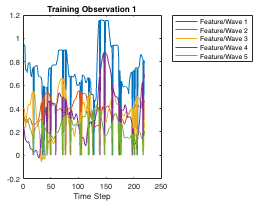

legend("Feature/Wave " + string(1:numFeatures), 'Location','northeastoutside')

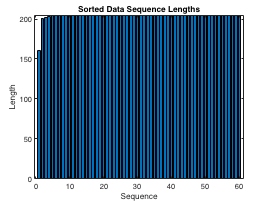

% Sort Data by Sequence Lengths
numObservations = numel(XTrain);
for i=1:numObservations
    sequence = XTrain{i};
    sequenceLengths(i) = size(sequence,2);
end

[sequenceLengths,idx] = sort(sequenceLengths);
XTrain = XTrain(idx);
YTrain = categorical(YTrain(idx));

figure
bar(sequenceLengths)
ylim([0 205])
xlabel("Sequence")
ylabel("Length")
title("Sorted Data Sequence Lengths")

## Long Short-Term Memory Neural Network

% Setup
inputSize = 5;
numHiddenUnits = 100;
numClasses = 5;

layers = [...
    sequenceInputLayer(inputSize)
    bilstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   5×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 5 dimensions
     2   ''   BiLSTM                  BiLSTM with 100 hidden units
     3   ''   Fully Connected         5 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex


maxEpochs = 100;
miniBatchSize = floor(height(XTrain) / 2);


options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'InitialLearnRate',0.001, ...
    'GradientThreshold',1, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest', ...
    'Shuffle','never', ...
    'ValidationData',{XTest,categorical(YTest)},...
    'ValidationFrequency',30,...
    'Verbose',0, ...
    'Plots','training-progress');

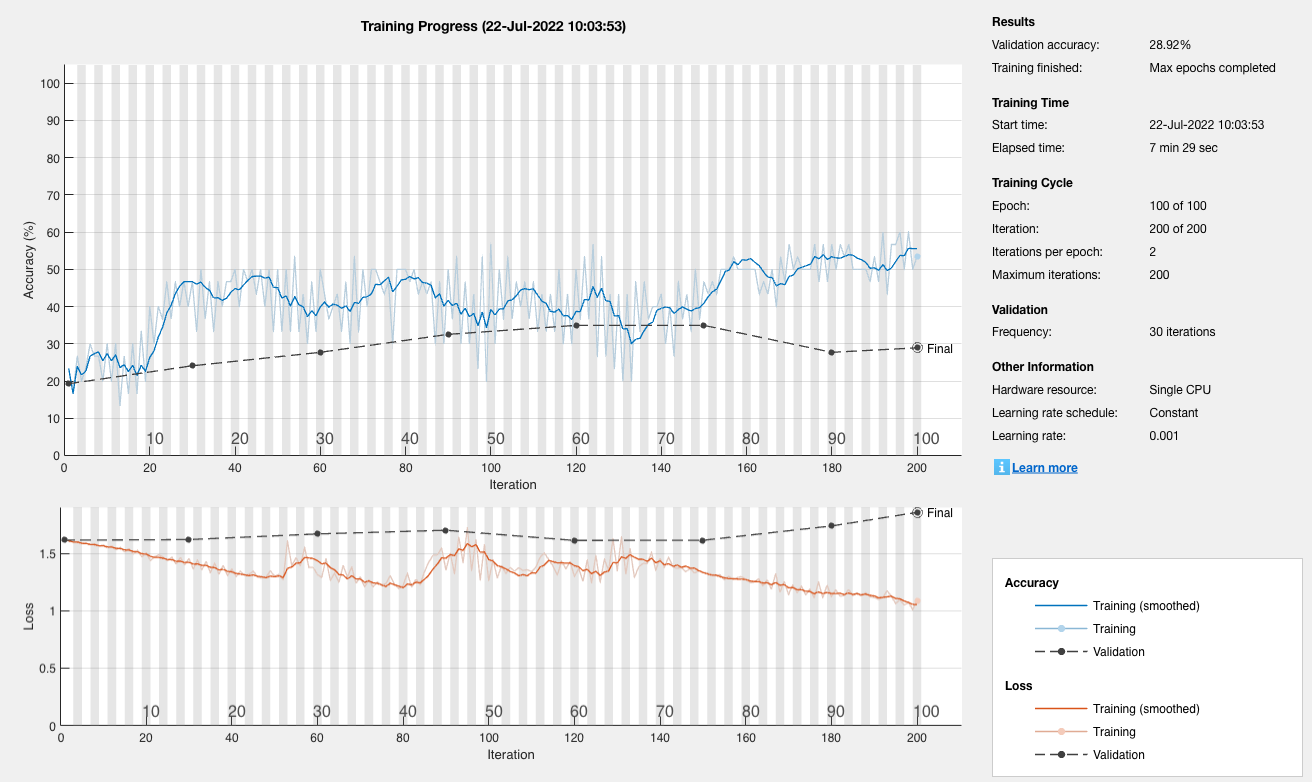

% Training
net = trainNetwork(XTrain,YTrain,layers,options);

## Testing Model

numObservationsTest = numel(XTest);
for i=1:numObservationsTest
    sequence = XTest{i};
    sequenceLengthsTest(i) = size(sequence,2);
end
[sequenceLengthsTest,idx] = sort(sequenceLengthsTest);
XTest = XTest(idx);
YTest = YTest(idx);

% miniBatchSize = 5;
YPred = classify(net,XTest, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest');
acc = sum(YPred == YTest)./numel(YTest)

acc = 0.2892

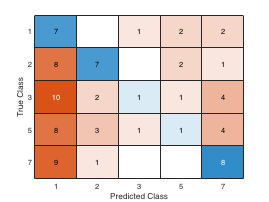

% Confusion table
trueLabels = categorical(YTest);
predLabels = YPred;
confusionchart(trueLabels,predLabels)